%Clase 2: Programación Lineal Entera (PLE) en Optimización

%Codigo para realizar programación lineal
% Datos del problema
    % Función Objetivo --> Z= 3X1 + 5X2
    % Restricciones:
    %2X1 + 3X2 <=12
    %-X1 + X2 <=3
    %X1,X2 >=0
Z = [-3 -5]; % Coeficientes para maximizar z, intlinprog minimiza, por eso signo negativo
A = [2 3; -1 1];
b = [12; 3];
lb = [0 0];
intcon = [1 2]; % Variables enteras

% Resolver problema entero
[x, fval, exitflag] = intlinprog(Z, intcon, A, b, [], [], lb, []);

Running HiGHS 1.7.0: Copyright (c) 2024 HiGHS under MIT licence terms
Coefficient ranges:
  Matrix [1e+00, 3e+00]
  Cost   [3e+00, 5e+00]
  Bound  [0e+00, 0e+00]
  RHS    [3e+00, 1e+01]
Presolving model
2 rows, 2 cols, 4 nonzeros  0s
2 rows, 2 cols, 4 nonzeros  0s
Objective function is integral with scale 1

Solving MIP model with:
   2 rows
   2 cols (0 binary, 2 integer, 0 implied int., 0 continuous)
   4 nonzeros

        Nodes      |    B&B Tree     |            Objective Bounds              |  Dynamic Constraints |       Work      
     Proc. InQueue |  Leaves   Expl. | BestBound       BestSol              Gap |   Cuts   InLp Confl. | LpIters     Time

         0       0         0   0.00%   -38             inf                  inf        0      0      0         0     0.0s
 R       0       0         0   0.00%   -19.8           -18               10.00%        0      0      0         2     0.0s
 C       0       0         0   0.00%   -19             -19                0.00%        2  


if exitflag == 1
    fprintf('Solución óptima encontrada:\n');
    fprintf('x1 = %.0f\n', x(1));
    fprintf('x2 = %.0f\n', x(2));
    fprintf('Valor óptimo z = %.2f\n', -fval);
else
    disp('No se encontró solución óptima.');
end

Solución óptima encontrada:


x1 = 3


x2 = 2


Valor óptimo z = 19.00


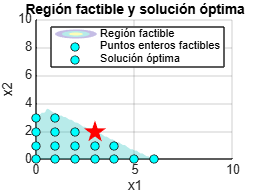


%Plotear la solución graficamente
% Crear rejilla para graficar la región factible
[x1, x2] = meshgrid(0:0.1:10, 0:0.1:10);

% Restricciones
r1 = 2*x1 + 3*x2 <= 12;
r2 = -x1 + x2 <= 3;
regionFactible = r1 & r2;

% Graficar región factible
figure;
hold on;
contourf(x1, x2, regionFactible, [1 1], 'LineColor', 'none', 'FaceAlpha', 0.3);
xlabel('x1');
ylabel('x2');
title('Región factible y solución óptima');
grid on;

% Graficar puntos enteros factibles
for i=0:floor(max(x1(:)))
    for j=0:floor(max(x2(:)))
        if (2*i + 3*j <= 12) && (-i + j <= 3)
            plot(i,j,'ko','MarkerFaceColor','cyan');
        end
    end
end

% Graficar solución óptima
plot(x(1), x(2), 'rp', 'MarkerSize', 15, 'MarkerFaceColor', 'red');
legend('Región factible', 'Puntos enteros factibles', 'Solución óptima');
hold off;